# Here we test the cross data predictive capacity of the rs-fMRI signatures

## study 6

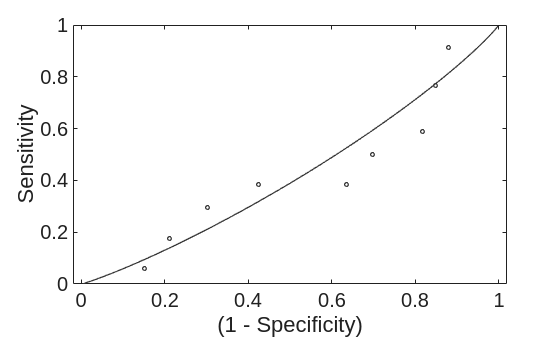

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_UESTC_s6.mat'))

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
FC = FC(32:end, parcel_idx);
label = [ones(34, 1); -ones(33, 1)];

load(fullfile(datadir, "A_MDD_pls_decoder_study7.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 6: ACC = 53.73% ± 6.091%, P = 0.7147, AUC = 0.4274, d = -0.2822 


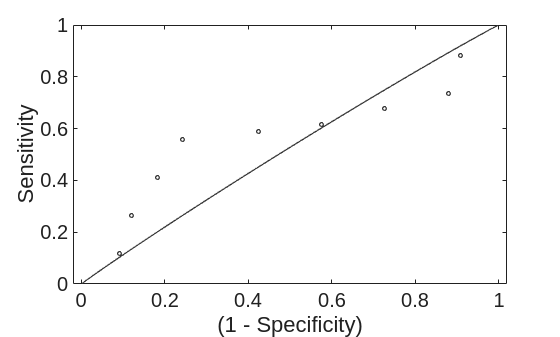


load(fullfile(datadir, "A_MDD_pls_decoder_study8.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 6: ACC = 65.67% ± 5.801%, P = 0.01942, AUC = 0.5744, d = 0.06931 


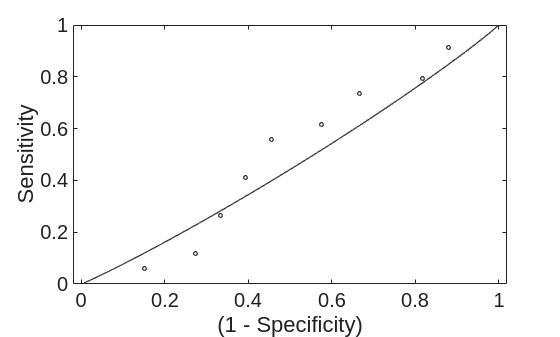


load(fullfile(datadir, "A_MDD_pls_decoder_study9.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 6: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 6: ACC = 56.72% ± 6.053%, P = 0.3927, AUC = 0.4982, d = -0.1461 


## study 7

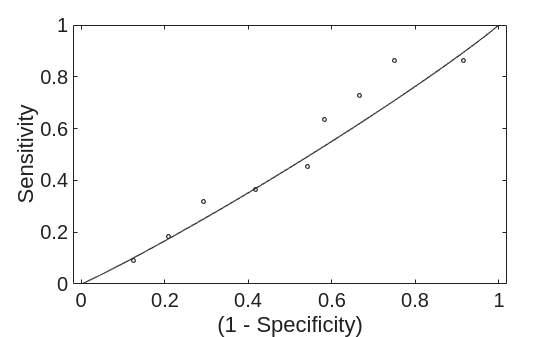

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_Chongqing_s6.mat'))

FC = atanh(FC);
FC(isnan(FC)) = 0;
FC(~isfinite(FC)) = 0;
label = [-ones(24, 1); ones(30, 1)];
included =  patient ~=2;
FC = FC(included, parcel_idx);
label = label(included);

load(fullfile(datadir, "A_MDD_pls_decoder_study6.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 7: ACC = 54.35% ± 7.344%, P = 0.8846, AUC = 0.5133, d = -0.1263 


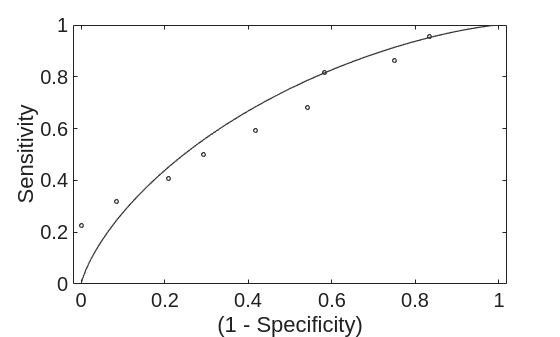


load(fullfile(datadir, "A_MDD_pls_decoder_study8.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 7: ACC = 67.39% ± 6.912%, P = 0.05309, AUC = 0.6828, d = 0.6886 


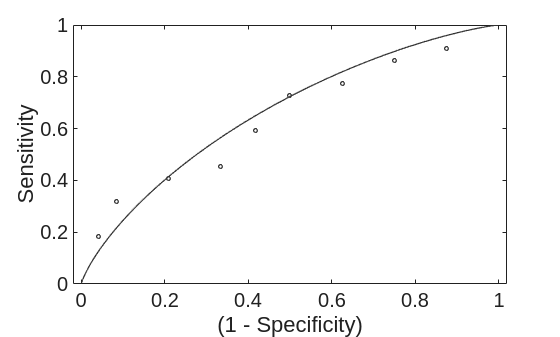


load(fullfile(datadir, "A_MDD_pls_decoder_study9.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 7: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 7: ACC = 65.22% ± 7.022%, P = 0.1027, AUC = 0.6629, d = 0.5941 


## study 8

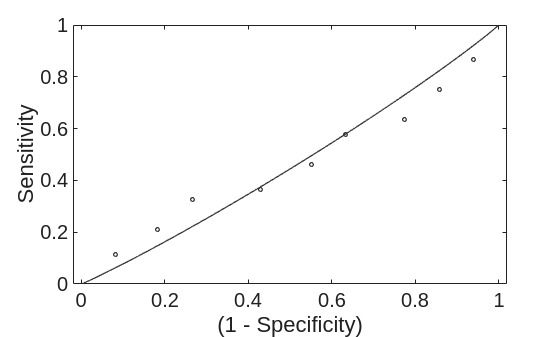

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_Chongqing2_s6.mat'))

FC = atanh(FC);
FC(~isfinite(FC)) = 0;
FC = FC(~excluded, parcel_idx);
label = label(~excluded);
label(label==0) = -1;

load(fullfile(datadir, "A_MDD_pls_decoder_study6.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 8: ACC = 52.48% ± 4.969%, P = 0.9215, AUC = 0.4643, d = -0.1408 


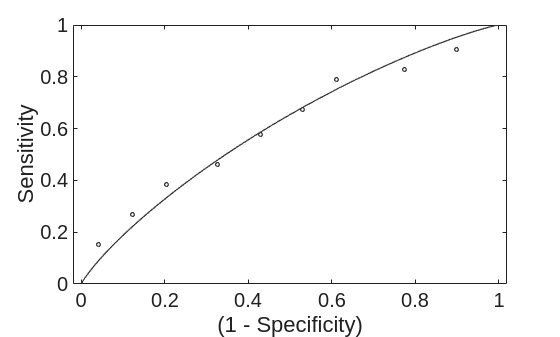


load(fullfile(datadir, "A_MDD_pls_decoder_study7.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 7 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 8: ACC = 62.38% ± 4.82%, P = 0.03575, AUC = 0.6232, d = 0.3966 


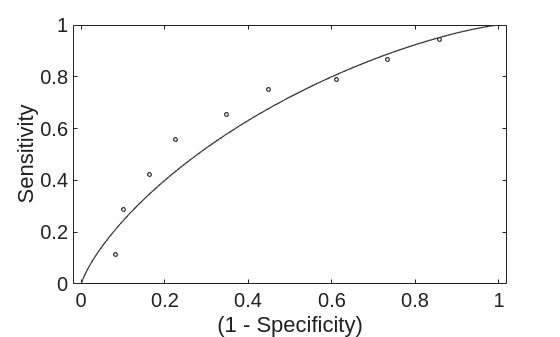


load(fullfile(datadir, "A_MDD_pls_decoder_study9.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 9 signature predicts study 8: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 9 signature predicts study 8: ACC = 67.33% ± 4.667%, P = 0.001825, AUC = 0.686, d = 0.5895 


## study 9

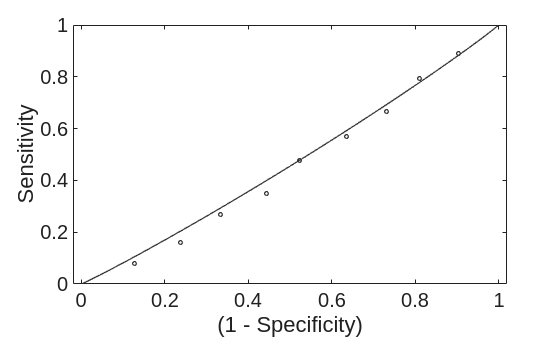

clear, clc
datadir = '/media/dell/zhou/A_arousal_analysis/data';
load(fullfile(datadir, 'A_arousal_connectivity_patterns.mat'), "parcel_idx")
load(fullfile(datadir, 'FC_BANDA_s6.mat'))

FC_run1 = atanh(FC_run1);
FC_run1(FC_run1==0) = NaN;
FC_run1(~isfinite(FC_run1)) = NaN;
FC_run1(outlier_run1,:) = NaN; % num of spikes > num of timepoints * 0.25
FC_run2 = atanh(FC_run2);
FC_run2(FC_run2==0) = NaN;
FC_run2(~isfinite(FC_run2)) = NaN;
FC_run2(outlier_run2,:) = NaN; % num of spikes > num of timepoints * 0.25

FC = [];
FC(:, :, 1) = FC_run1;
FC(:, :, 2) = FC_run2;
clear FC_*
FC = mean(FC, 3, 'omitnan');
FC = FC(:, parcel_idx);
excluded_fmri = outlier_run1 & outlier_run2;

T = readtable(fullfile(datadir, 'ndar_subject01.csv'),'VariableNamingRule', 'preserve', 'TreatAsEmpty', 'n/a');
control = false(206,1);
depression = false(206,1);
anxiety = false(206,1);
for i = 1:206
    idx = strcmp(T.src_subject_id, subIDs{i}(5:end)) & strcmp(T.visit,'T1');
    if sum(idx) == 1
    if strcmp(T.phenotype(idx),'Control')
        control(i) = true;
    elseif strcmp(T.phenotype(idx),'Depression')
        depression(i) = true;
    elseif strcmp(T.phenotype(idx),'Anxiety')
        anxiety(i) = true;
    end
    end
end

FC_depr = FC(depression & ~excluded_fmri,:);
FC_con = FC(control & ~excluded_fmri,:);
clear FC
ndepr = size(FC_depr, 1);
ncon = size(FC_con, 1);
label = [ones(ndepr,1); -ones(ncon, 1)];
FC = [FC_depr; FC_con];

load(fullfile(datadir, "A_MDD_pls_decoder_study6.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput'); 

fprintf('\n Study 6 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 6 signature predicts study 9: ACC = 51.59% ± 4.452%, P = 0.7894, AUC = 0.464, d = -0.1132 


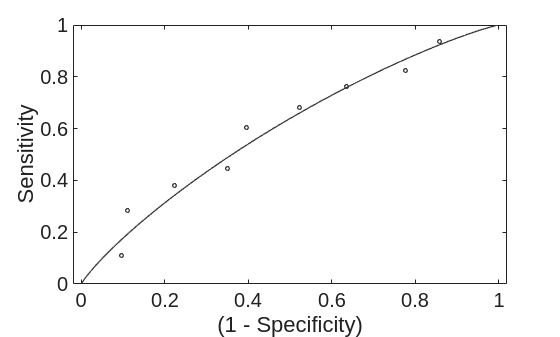


load(fullfile(datadir, "A_MDD_pls_decoder_study7.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 7 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 7 signature predicts study 9: ACC = 61.11% ± 4.343%, P = 0.01582, AUC = 0.6159, d = 0.3558 


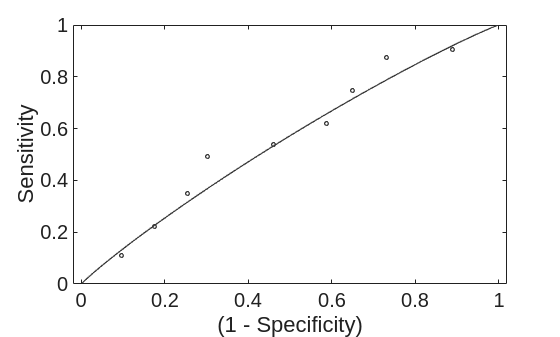


load(fullfile(datadir, "A_MDD_pls_decoder_study8.mat"), 'bpls');
pred_label = [ones(numel(label), 1) FC] * bpls;
figure;
roc = roc_plot(pred_label, label>0, 'nooutput');

fprintf('\n Study 8 signature predicts study 9: ACC = %.04g%% ± %.04g%%, P = %.04g, AUC = %.04g, d = %.04g \n', roc.accuracy*100, roc.accuracy_se*100, roc.accuracy_p, roc.AUC, roc.Gaussian_model.d_a)


 Study 8 signature predicts study 9: ACC = 60.32% ± 4.358%, P = 0.02554, AUC = 0.5753, d = 0.1824 
